% Os dois primeiros exemplos são testes de conceito.

## Conexões não implementadas

Ainda não temos nenhuma conexão diferente de TCP.

Reservada para em caso no futuro seja desejável outras formas de conexão.

try     
    Analysers.Analyser.connGPIB('1234')
catch exception
    disp(exception.message)
end

Analyser: Conexão GPIB não implementada.


## Execução com o simulador SA2500PC

Alocação dinâmica ainda não implementada (perfumaria prevista):

Caso só passe o IP, teríamos uma opção de auto discovery:

% Auto discovery
try     
    Analysers.Analyser.connTCP("localhost");
catch exception
    disp(exception.message)
end

Analyser: Autodiscovery não implementado


% 
% % Ref. portas a varrer:
% % 5025  - Keysight e R&S
% % 5555  - R&S EB500
% % 9001  - Anritsu
% % 34835 - Tektronix 

Para o caso do Instrumento simulado, o download está em [SA2500PC](https://anatel365-my.sharepoint.com/:f:/r/personal/eric_anatel_gov_br/Documents/Softwares/Tektronix/SA2500PC?csf=1&web=1&e=Qde3u5).

Conectando e respondendo à identificação:

% disp('Propriedades:')
% callTCP = Analysers.Analyser.connTCP("localhost", 34835) % Simulador
callTCP = Analysers.Analyser.connTCP("192.168.48.2", 34835)

callTCP =   dictionary (string ⟼ string) with 6 entries:

    "Factory" ⟼ "TEKTRONIX"
    "model"   ⟼ "SA2500"
    "serial"  ⟼ "B040211"
    "version" ⟼ "7.050"
    "ip"      ⟼ "192.168.48.2"
    "port"    ⟼ "34835"


## **Instância dinâmica. **

Cada fabricante deve ter, na pasta 'Analysers', sua classe como mesmo nome de sua superclasse (prop:Factory), e cada especifidade de um certo modelo (prop:model) deve estar com o mesmo nome, o que permite escalonar e isolar os componentes em uma interface unificada, e granularizada para o serviço esperado.

O 'Analyser' deve conter todos os comandos genéricos da SCPI (Standard Commands for Programmable Instruments) e IEEE 488.2 Common Commands, este último inicia por um asterisco..

Com base na IDN que o instrumento responde, a instância sempre herda todos os comandos do 'Analyser'.

No caso, o "is a" está representado no classdef como "classdef TEKTRONIX < Analyser", ou seja, Um Tektronix é um analisador, e o SP2500 é um Tektronx ("classdef SA2500PC < TEKTRONIX")

Neste caso herda os comuns e sobrecarrega os comandos do Tektronix, e os específicos do modelo SA2500PC:

disp('Instancia Classes:')

Instancia Classes:


obj = Analysers.Analyser.instance(callTCP);

    "Analyer: Base de comando do fabricante"    "TEKTRONIX"



O simulador fecha quando recebe o comando de reset, então só fingimos o reset (com sobrecarga de método) para evitar isso na implementação específica do modelo. 

Um instrumento real não terá o sufixo PC e portanto automaticamente não herdará esse método, o que possibilita compartilar comandos e especificar no modelo o que for diferente nele.

obj.scpiReset;

Analyer.scpiReset: Criando nova conexão TCP.


Comandos gerais de inicialização:

obj.startUp()

TEKTRONIX: Start Ok.


Teste geral de conectividade (SCPI) com reuso da conexão TCP.

O "ping" verifica se a conexão ainda está ativa e remove ela para nova conexão.

obj.ping()

Analyser.ping: Mesma conexão
Analyser.ping: Resposta IDN recebida:
TEKTRONIX,SA2500,B040211,7.050


Obtém parâmetros do objeto: 

disp('getSpan:')

getSpan:


disp(obj.getSpan())

200000000



disp('Parâmetros:')

Parâmetros:


obj.getParms()

ans =   dictionary (string ⟼ string) with 10 entries:

    "Function"  ⟼ "NORM"
    "AVGCount"  ⟼ "20"
    "Detection" ⟼ "POS"
    "UnitPower" ⟼ "DBM"
    "FStart"    ⟼ "759000000"
    "FStop"     ⟼ "959000000"
    "ResAuto"   ⟼ "1"
    "Res"       ⟼ "200000"
    "InputGain" ⟼ "0"
    "Att"       ⟼ "50"


## Operação

Aqui perguntamos se o parâmetro corresponde ao que foi solicitado (assert). E verificamos as respostas no simulador em tempo real:

disp('Observação do comportamento:')

Observação do comportamento:



% Esse bloco try é para liberar a conexão em caso de erro, 
% porque o live script não chama o destrutor da classe automaticamente.
try

    % Testes
    obj.setFreq(120000000)
    obj.setSpan(50000)
    assert(str2double(obj.getSpan) == 50000, 'O Span não foi ajustado.')
    obj.setRes(2000)
    assert(str2double(obj.getRes) == 2000, 'O Span não foi ajustado.')

    % pause(1)
    obj.setFreq(100000000)
    obj.setSpan(10000)
    
    % disp('Nova conexão simulada pelo ping (caso não responda):')
    obj.disconnect();
    
    % Isso gera um alerta na janela do simulador,
    % mas não retorna erro.
    try
        RBW = obj.getRes();
        assert(str2double(RBW) == 2000, 'A Resolução foi alterada automaticamente.')
    catch exception
        disp('Resolução alterada automaticamente para:')
        disp(RBW)
    end

Analyer.getCMD: Criando nova conexão.


Resolução alterada automaticamente para:


1000


    
    % pause(1)
    disp('Amostra em faixa larga')

Amostra em faixa larga


    obj.setFreq(88000000, 108000000)
    obj.setRes(20000) % Warning: Data out of range

    wtrace = obj.getTrace(1);

    disp('Trace em faixa larga:')

Trace em faixa larga:


    
    % Só as 10 primeiras linhas
    disp(wtrace (1:10,:));

      freq        value 
    _________    _______

      8.8e+07    -120.24
    8.804e+07    -122.87
    8.808e+07    -114.95
    8.812e+07    -115.21
    8.816e+07    -113.02
     8.82e+07       -117
    8.824e+07    -116.39
    8.828e+07    -110.72
    8.832e+07    -110.61
    8.836e+07    -113.03



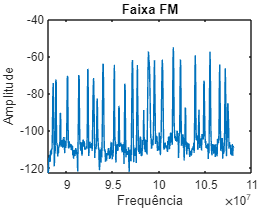


    plot(wtrace.freq,wtrace.value,"DisplayName","value");
    % drawnow;

    % Add xlabel, ylabel, title, and legend
    xlabel("Frequência");
    ylabel("Amplitude");
    title("Faixa FM");

    legend('off');
    % drawnow;
    
    try
        assert(str2double(obj.getSpan) == 10000, 'O Span não foi ajustado.')
    catch
        disp('Se atribuir o span depois.')
        disp('gera erro "out of range"')
    end

Se atribuir o span depois.


gera erro "out of range"


    
    % pause(1)
    % Observar que o com Spectrum o RBW Auto em verde
    obj.setRes('Auto')
    obj.setFreq(88000000, 108000000)
    
    % % Para observar a faixa em auto level
    % pause(2)

    % Escolhe uma portadora FM para análise
    freq = 100300000;
    
    obj.setSpan(500000)
    obj.setFreq(freq)
    assert(str2double(obj.getSpan) == 500000, 'O Span não foi ajustado.')
    
    obj.preAmp('On')
    
    % Teste dos níveis de atenuação
    % Para observar abrir o menu Spectrum -> More -> Ampl
    for attstep = 5:5:50
        obj.setAtt(attstep);
        %pause(0.5)

        % O pré desativa sozinho com att acima de 15dB
        % Mesmo expressamente solicitado, sem erro:
        obj.preAmp('On')
    end




    trace = obj.getTrace(1);

    disp('Trace para análise:')

Trace para análise:


    
    % Só as 10 primeiras linhas
    disp(trace (1:10,:));

       freq        value 
    __________    _______

    1.0005e+08     -123.1
    1.0005e+08    -118.88
    1.0005e+08    -125.56
    1.0005e+08    -120.19
    1.0005e+08    -118.29
    1.0006e+08     -119.3
    1.0006e+08    -119.71
    1.0006e+08       -120
    1.0006e+08    -118.65
    1.0006e+08    -119.03



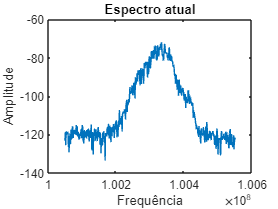

    
    
    
    % Plota o Trace
    plot(trace.freq,trace.value,"DisplayName","value");
    
    % Add xlabel, ylabel, title, and legend
    xlabel("Frequência");
    ylabel("Amplitude");
    title("Espectro atual");

    legend('off');


    trcs = fcn.getTracesFromUnit(obj, 50);

ans = "Trace 1"

ans = "Trace 2"

ans = "Trace 3"

ans = "Trace 4"

ans = "Trace 5"

ans = "Trace 6"

ans = "Trace 7"

ans = "Trace 8"

ans = "Trace 9"

ans = "Trace 10"

ans = "Trace 11"

ans = "Trace 12"

ans = "Trace 13"

ans = "Trace 14"

ans = "Trace 15"

ans = "Trace 16"

ans = "Trace 17"

ans = "Trace 18"

ans = "Trace 19"

ans = "Trace 20"

ans = "Trace 21"

ans = "Trace 22"

ans = "Trace 23"

ans = "Trace 24"

ans = "Trace 25"

ans = "Trace 26"

Analyser: Aguardando sincronismo (1/2): ...
:INITiate:IMMediate


ans = "Trace 27"

ans = "Trace 28"

ans = "Trace 29"

ans = "Trace 30"

Analyser: Aguardando sincronismo (1/2): ...
:INITiate:IMMediate


ans = "Trace 31"

ans = "Trace 32"

ans = "Trace 33"

ans = "Trace 34"

ans = "Trace 35"

ans = "Trace 36"

ans = "Trace 37"

ans = "Trace 38"

ans = "Trace 39"

ans = "Trace 40"

ans = "Trace 41"

ans = "Trace 42"

ans = "Trace 43"

ans = "Trace 44"

ans = "Trace 45"

Analyser: Aguardando sincronismo (1/2): ...
:INITiate:IMMediate


ans = "Trace 46"

ans = "Trace 47"

ans = "Trace 48"

ans = "Trace 49"

ans = "Trace 50"


    % Verificação adicional.
    if isnan(trcs)
        warning('Trace com NaN')
    end

    disp("Total size:")

Total size:


    size(trcs)

ans =     50   501


    disp(trcs)

 -124.7716 -125.0332 -129.6411 -124.4958 -120.3806 -122.3472 -117.1556 -124.8356 -124.4888 -125.9429 -123.7836 -117.2339 -120.8615 -119.4148 -116.0637 -115.0579 -116.4643 -120.6358 -121.5421 -121.9835 -123.3146 -123.8933 -126.3697 -122.1906 -119.9894 -121.2245 -119.1369 -121.2451 -120.5609 -121.5293 -121.1653 -122.4170 -124.6396 -121.7139 -119.1956 -124.5325 -119.9572 -119.4142 -121.2967 -122.3104 -124.7149 -120.7480 -127.4581 -131.8235 -123.7542 -118.2520 -121.9419 -118.8797 -122.2406 -119.4042 -118.8984 -113.6148 -128.3574 -125.3988 -121.3279 -123.3902 -119.3879 -122.6543 -125.7265 -123.8634 -120.1029 -121.2280 -115.5695 -124.6774 -122.9282 -119.8781 -116.7437 -117.6992 -123.3165 -126.1659 -120.4356 -117.2382 -115.6595 -116.7602 -119.0044 -118.3102 -116.0253 -121.4719 -119.7304 -118.9726 -117.5527 -118.2895 -117.3959 -112.4090 -114.1971 -120.0210 -119.7572 -119.4901 -118.8668 -118.4469 -121.2545 -117.4663 -111.4132 -121.2574 -122.0842 -117.0247 -124.8532 -119.6646 -119.7028 -113.9208


    % % Um tempo para o analisador respirar
    % % Porque eventualmente ele não responde
    % pause(0.2)

    freq = 100300200;
    obj.setFreq(freq)
    disp('Leitura do marcador:')

Leitura do marcador:


    nivel = obj.getMarker(freq, 1);
    fprintf('Em %i MHz o nível é: %f\n', freq, nivel);

Em 100300200 MHz o nível é: -73.478180



    if isnan(nivel)
        warning('Nível não retornado.');
    end

catch exception
    % Encerra ativamente a conexão
    % Para liberar a porta em caso de erro
    obj.disconnect();
    error('TestTektronix: %s', exception.identifier);
end

% Se tudo der certo, encerra a conexão.
obj.disconnect()


disp("Pronto")

Pronto
